% This matlab live script uses equations and methods derived from the 
% paper 'How to uniquely specify a pitched baseball's seam orientation'
% by Aden Seaman to converts baseball pitching data (spin axis, seam lat, 
% seam long, and rotation around spin axis theta alpha) obtained from 
% Trackman to the basis of baseball frame (standard seam orientation), 
% which is defined in the paper. 

% Also, it plots the calculated seam orientation relative to the spin axis 
% in 3D, and generates spin animation.

% The equation of seam line is from 
% http://www.darenscotwilson.com/spec/bbseam/bbseam.html.

% Coordinate System Specifications:
% The origin is at the center of the baseball
% The positive y axis points to the pitcher
% The positive x axis points to the right of catcher's perspective
% The positive z axis points to the sky


% Calculate the basis of baseball frame:

% Input numbers
a1 = 0;
a2 = 1;
a3 = 0;

% Handle exception
if ((a1^2 + a2^2 + a3^2) > 1.01 || (a1^2 + a2^2 + a3^2) < 0.99)
    ME = MException('myComponent:inputError', 'Please enter a unit vector.');
    throw(ME);
end

% Input angles
lat_d = 0;
long_d = 0;
theta_alpha_d = 0;

% Handle corner case when seam lat = 0
% Set theta alpha = seam long and set seam long to 0 in this case
if lat_d == 0
   theta_alpha_d = long_d;
   long_d = 0;
end

% Convert to radians
lat = lat_d*pi/180.0;
long = long_d*pi/180.0;
theta_alpha = theta_alpha_d*pi/180.0;

% Define rotation matrices
Rlat = [ cos(lat), -sin(lat), 0;
         sin(lat),  cos(lat), 0;
                0,         0, 1];

Rlong = [  cos(long), 0, sin(long);
                   0, 1,         0;
          -sin(long), 0, cos(long)];

Ralpha = [  cos(theta_alpha), 0, sin(theta_alpha);
                           0, 1,                0;
           -sin(theta_alpha), 0, cos(theta_alpha)];

% Calculate theta k and k vector based on spin axis
if a2 == 1
    k = 0;
    Rk = eye(3); % special case, k is undefined, Rk not needed
    k_vector = [1 1 1]; % Use a random vector for k_vector since undefined
elseif a2 == -1
    k = pi;
    % Another special case, k is undefined, rotate around z axis for pi
    Rk = [ cos(k), -sin(k), 0;
           sin(k),  cos(k), 0;
                0,       0, 1];
    k_vector = [0 0 1]; % Make k_vector z axis 
else
    if a2 >= 0
        k = asin(sqrt(a3^2 + a1^2));
        k_vector = [a3/(a1^2 + a3^2)^(1/2), 0, -a1/(a1^2 + a3^2)^(1/2)];
    elseif a2 < 0
        k = pi - asin(sqrt(a3^2 + a1^2));
        k_vector = [a3/(a1^2 + a3^2)^(1/2), 0, -a1/(a1^2 + a3^2)^(1/2)];
    end
    
    % Rotation matrix for Rk
    k1 = k_vector(1);
    k2 = k_vector(2);
    k3 = k_vector(3);
    
    Rk = [  cos(k) + (k1^2)*(1 - cos(k)),   k1*k2*(1 - cos(k)) - k3*sin(k), k1*k3*(1 - cos(k)) + k2*sin(k);
            k2*k1*(1 - cos(k)) + k3*sin(k),   cos(k) + (k2^2)*(1 - cos(k)), k2*k3*(1 - cos(k)) - k1*sin(k);
            k3*k1*(1 - cos(k)) - k2*sin(k), k3*k2*(1 - cos(k)) + k1*sin(k),  cos(k) + (k3^2)*(1 - cos(k))];
end

% Calculate for rotations when plotting
center = [0 0 0]; % Rotation center
temp = Rk*Rlat;
y2 = temp(:, 2); % Rotation axis for seam long
z1 = Rk(:, 3); % Rotation axis for seam lat
k_d = k*180/pi; % Convert k to degree 
spin_axis = [a1 a2 a3]; % Get spin axis

% Define the equation for basis of standard seam orientation
P4 = Rk*Ralpha*Rlat*Rlong;

% Get result and output
result = P4;
disp('Basis of Standard Seam Orientation:');

Basis of Standard Seam Orientation:


disp(result);

     1     0     0
     0     1     0
     0     0     1



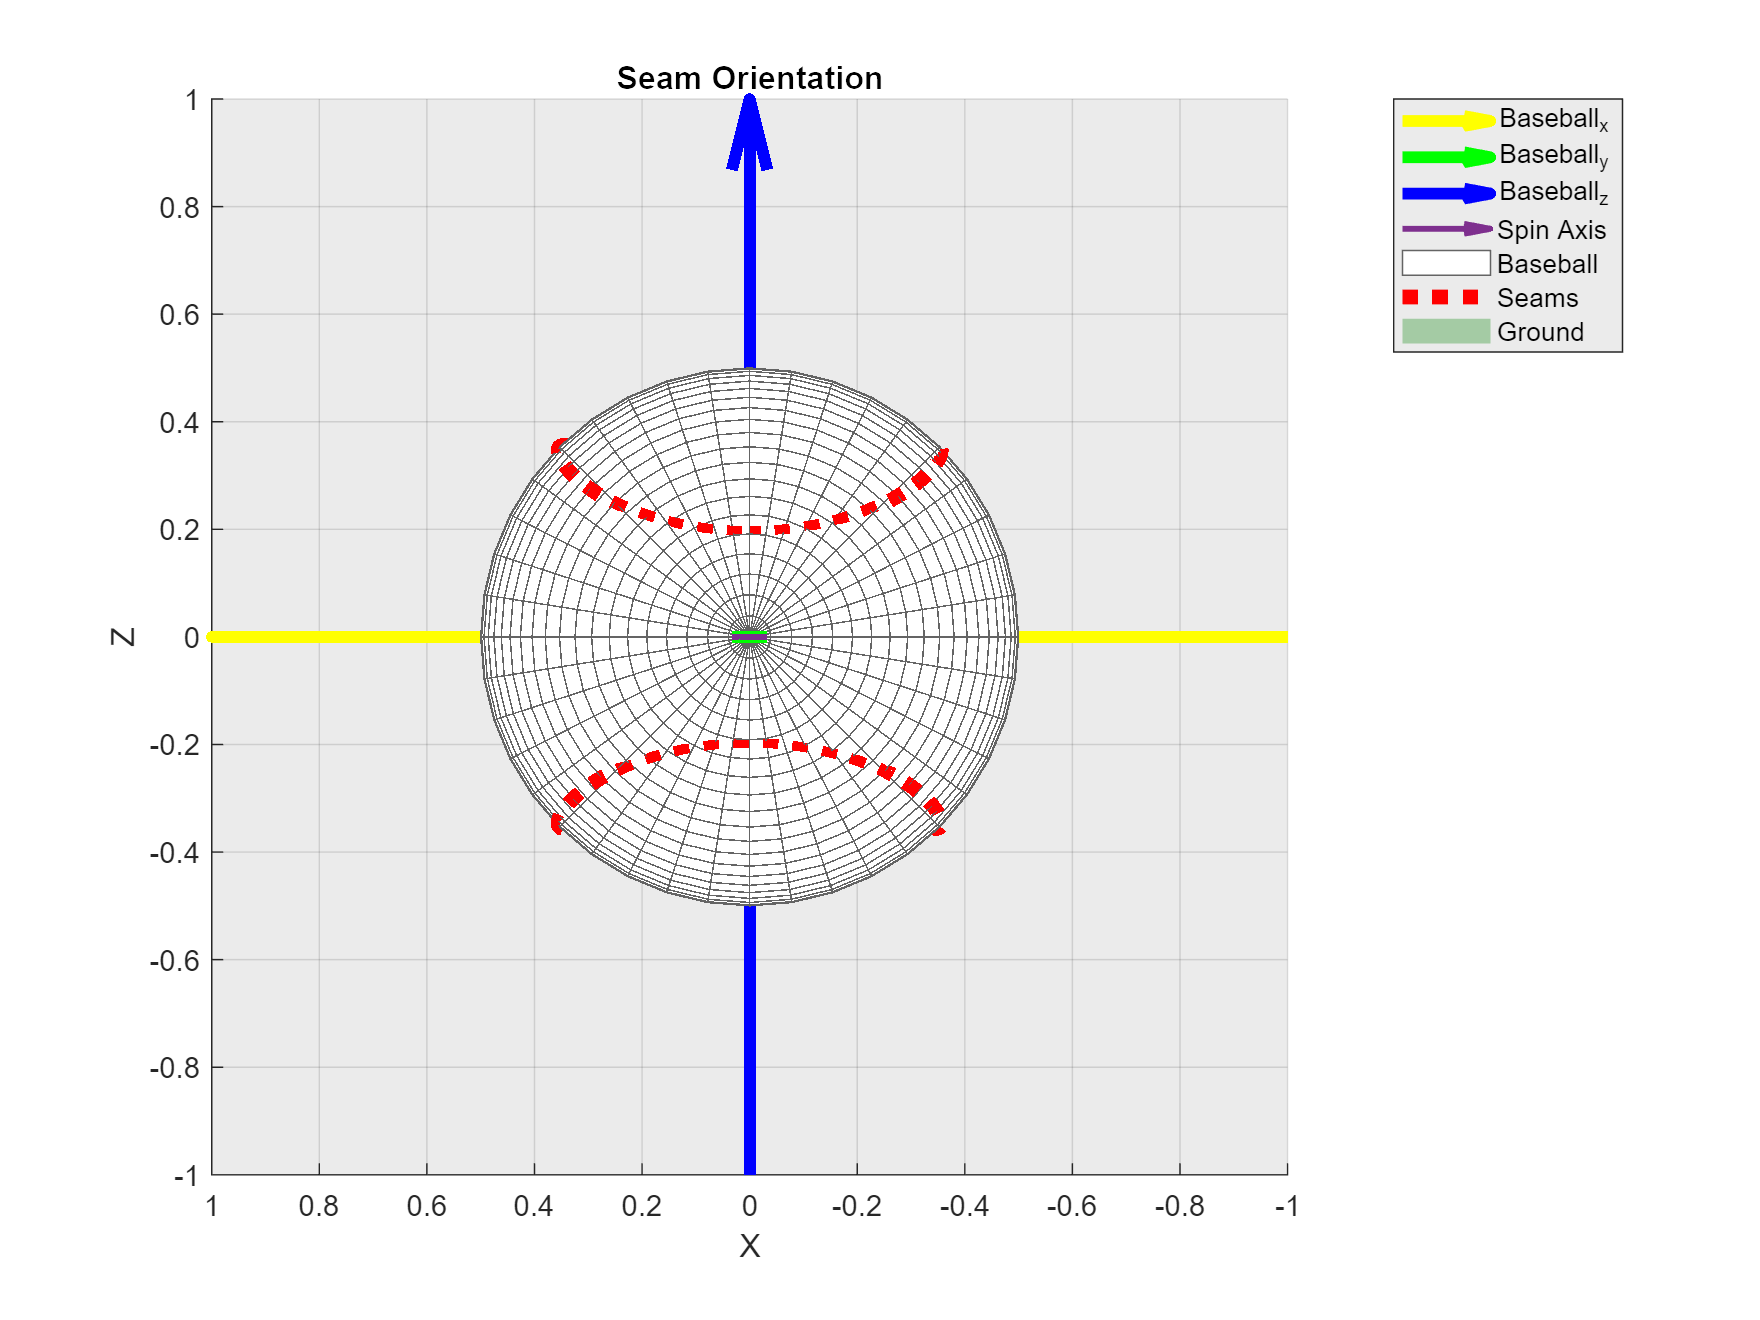



% Plot:
% Draw the basis of baseball (standard seam orientation)
figure
hold on
basis_x = quiver3(-result(1,1), -result(2,1), -result(3,1), result(1,1), result(2,1), result(3,1), 2, 'y-', 'LineWidth', 4);
basis_y = quiver3(-result(1,2), -result(2,2), -result(3,2), result(1,2), result(2,2), result(3,2), 2, 'g-', 'LineWidth', 4);
basis_z = quiver3(-result(1,3), -result(2,3), -result(3,3), result(1,3), result(2,3), result(3,3), 2, 'b-', 'LineWidth', 4);

% Draw spin axis
quiver3(-a1, -a2, -a3, a1, a2, a3, 2, 'LineWidth', 2);

% Draw a sphere representing baseball
[X,Y,Z] = sphere(40);
ball_radius = 0.5;

% Account for axes offset
% baseballx = y, basebally = z, baseballz = x
% Also rotate to align the axes
ballx = Y;
bally = Z;
ballz = X;

s = surf(double(ball_radius*ballx), double(ball_radius*bally), double(ball_radius*ballz));
s.FaceColor = 'white'; % Ball color
s.EdgeColor = [100/255 100/255 100/255]; % Grid color
s.FaceAlpha = 1.0; % Transparency

% Rotate
rotate(s, k_vector, k_d, center);
rotate(s, z1, lat_d, center);
rotate(s, y2, long_d, center);
rotate(s, spin_axis, theta_alpha_d, center);

% Draw seam
alpha = 1:1:360;
% Convert to radian
alpha_r = alpha*pi/180.0;

% Calculate seam points
seamx = (1/13)*ball_radius*(9*cos(alpha_r) - 4*cos(3*alpha_r));
seamy = (1/13)*ball_radius*(9*sin(alpha_r) + 4*sin(3*alpha_r));
seamz = (12/13)*ball_radius*cos(2*alpha_r);

% Account for axes offset
% baseballx = y, basebally = z, baseballz = x
% Also rotate to align the axes
adjustedx = seamy;
adjustedy = seamz;
adjustedz = seamx;

seam_line = [adjustedx; adjustedy; adjustedz];
seam_line = result*seam_line; % Rotate to the basis

seamx = seam_line(1, :);
seamy = seam_line(2, :);
seamz = seam_line(3, :);

% Plot seam line
p = plot3(seamx, seamy, seamz, '-r', 'LineWidth', 5);
p.LineStyle = ':';

% Label and adjust settings
xlabel('X')
ylabel('Y')
zlabel('Z')
grid on
title('Seam Orientation')
set(gca,'color', [235/255 235/255 235/255]) % Background color
axis equal

% Adjust view
view_azimuth = 180;
view_elevation =  0;
view([view_azimuth view_elevation]) % View (default is pitcher's perspective)
axis([-1 1 -1 1 -1 1]) % Fix the axes

% Adjust figure size
x0 = 10;
y0 = 10;
width = 825;
height = 600;
set(gcf, 'position', [x0, y0, width, height]);

% Change the color of the x-y plane to be dark green
x_lim = get(gca, 'XLim');
y_lim = get(gca, 'YLim');
z_lim = get(gca, 'YLim');
pat = patch([x_lim(1), x_lim(2), x_lim(2), x_lim(1)], [y_lim(1), y_lim(1), y_lim(2), y_lim(2)], [z_lim(1) z_lim(1) z_lim(1) z_lim(1)], [0 0.5 0]);
pat.EdgeColor = 'none';
pat.FaceAlpha = 0.3;

legend('Baseball_x', 'Baseball_y', 'Baseball_z', 'Spin Axis', 'Baseball', 'Seams', 'Ground')

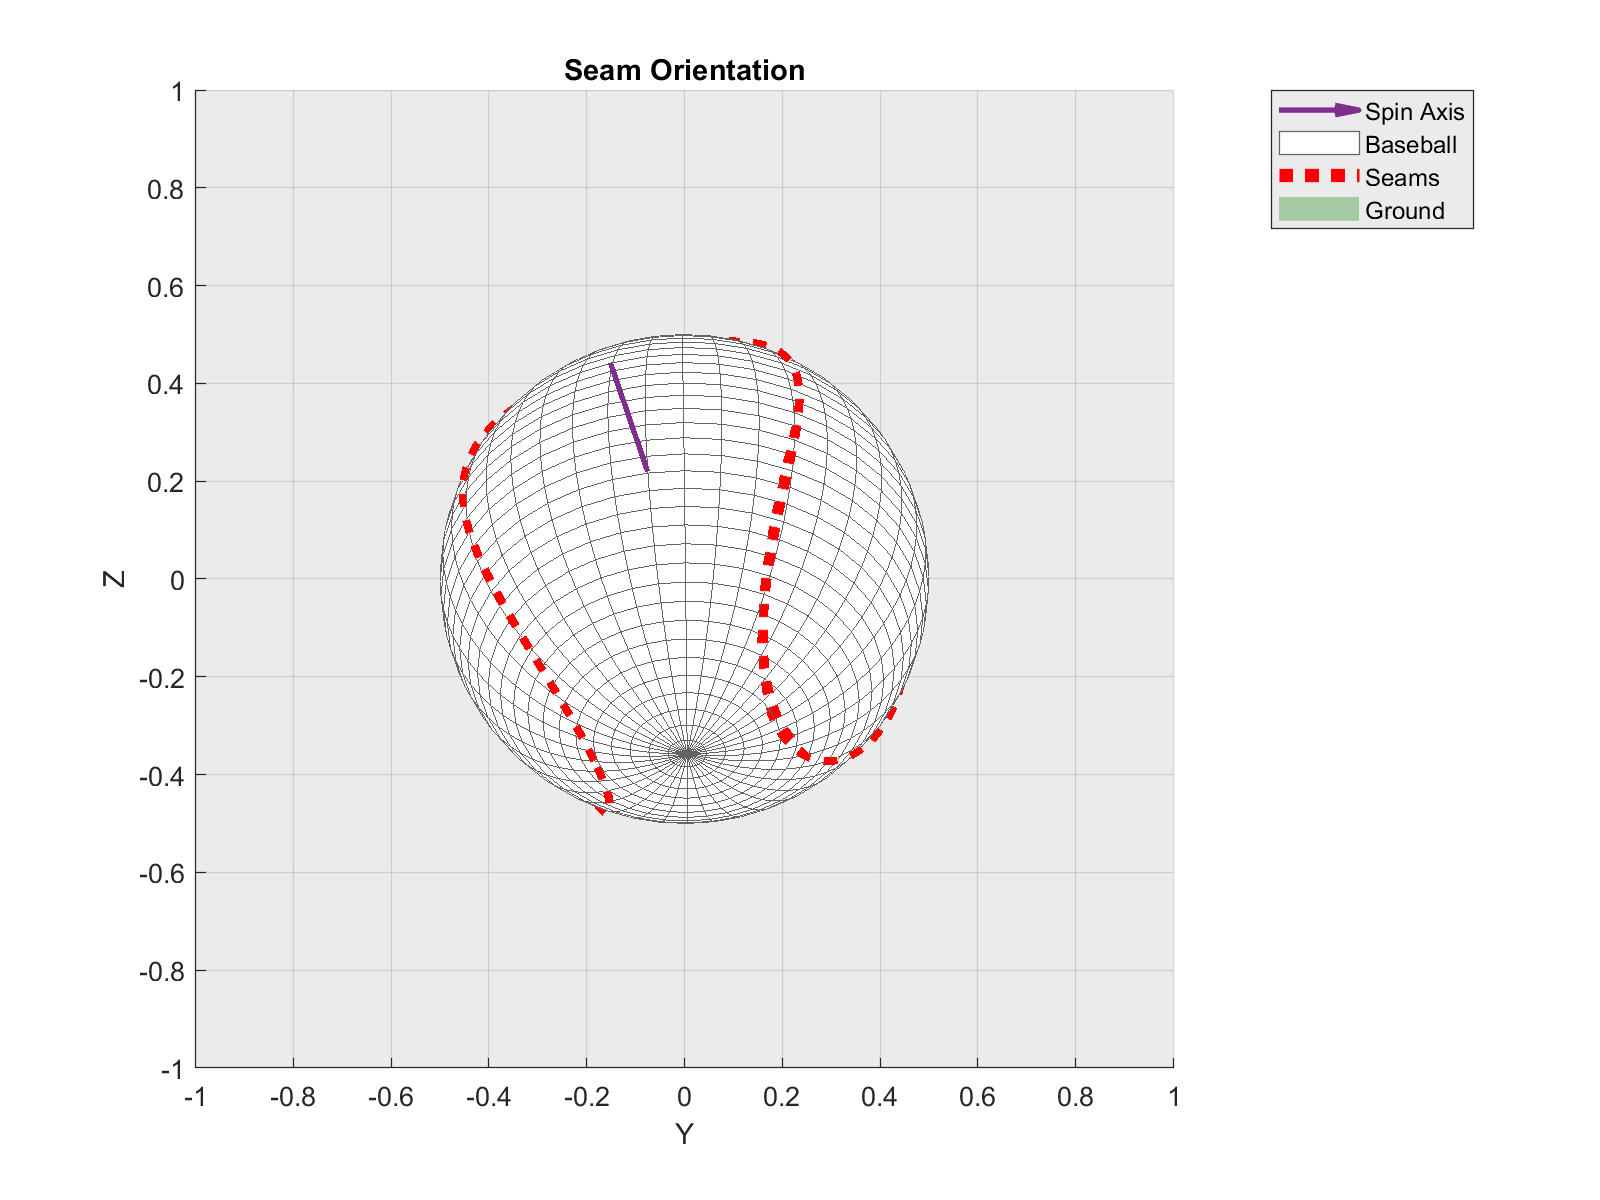

% Input RPM
rpm = 1000;
rotate_degree = 0.06*rpm;
  % Run this section

% Delete the baseball axes so we can see better
if isgraphics(basis_x)
    delete(basis_x);
end

if isgraphics(basis_y)
    delete(basis_y);
end

if isgraphics(basis_z)
    delete(basis_z);
end

if isgraphics(s) && isgraphics(p)
    % Spin the ball for about 1 sec
    for t = 1:1:100
        rotate(s, spin_axis, rotate_degree, center);
        rotate(p, spin_axis, rotate_degree, center);
    
        pause(0.01);
    end
else 
    disp('Please run the program first.');
end